# View Rotating 3-D Point Cloud

Load point cloud.

ptCloud = pcread("C:\Users\admin\Desktop\Lidar_DL\upsampling\sr\PointCloudSuperResolution.pytorch\data\pred2\ImageToStl.com_crop.pcd");

Define a rotation matrix and 3-D transform.

x = pi/180; 
R = [ cos(x) sin(x) 0 0
     -sin(x) cos(x) 0 0
      0         0   1 0
      0         0   0 1];

tform = affine3d(R);

Compute *x*-_y_ limits that ensure that the rotated teapot is not clipped.

lower = min([ptCloud.XLimits ptCloud.YLimits]);
upper = max([ptCloud.XLimits ptCloud.YLimits]);
  
xlimits = [lower upper];
ylimits = [lower upper];
zlimits = ptCloud.ZLimits;

Create the player and customize player axis labels.

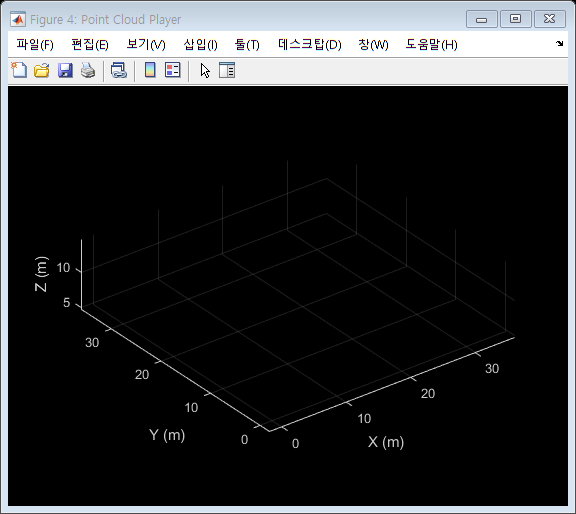

player = pcplayer(xlimits,ylimits,zlimits);

xlabel(player.Axes,'X (m)');
ylabel(player.Axes,'Y (m)');
zlabel(player.Axes,'Z (m)');

Rotate the teapot around the *z*-axis.

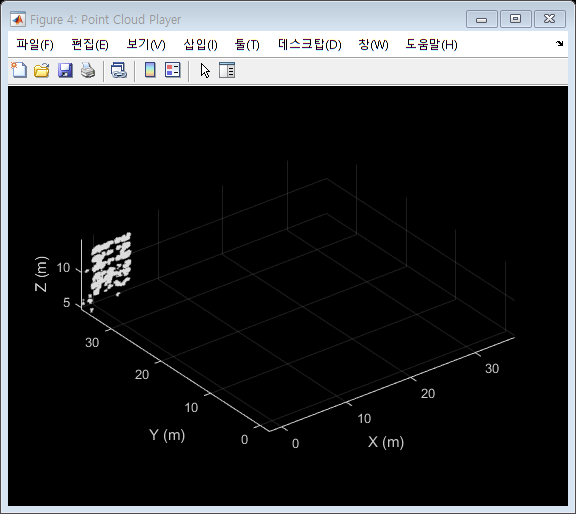

for i = 1:360      
    ptCloud = pctransform(ptCloud,tform);     
    view(player,ptCloud);     
end

*Copyright 2015 The MathWorks, Inc.*